# Storm Events Data

The goal of this case study is to **explore** storm events in various locations in the United States,  **analyze the frequency and damage costs **associated with different types of events and **identify the most costly events.**

  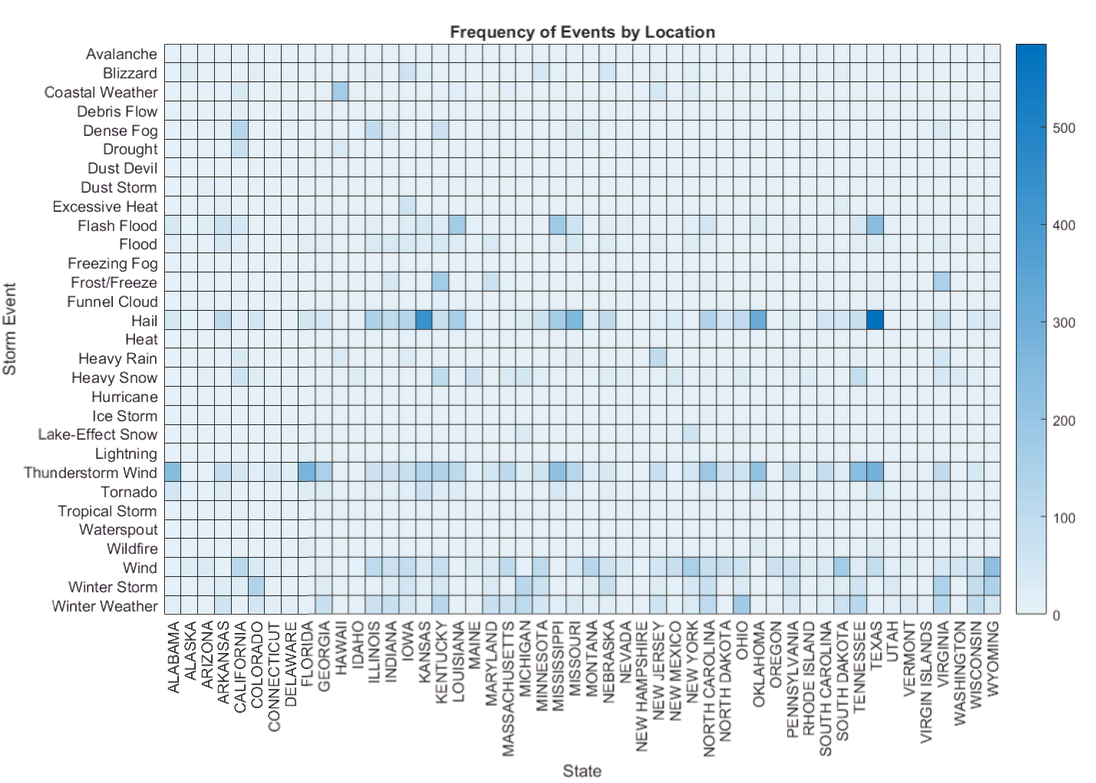                  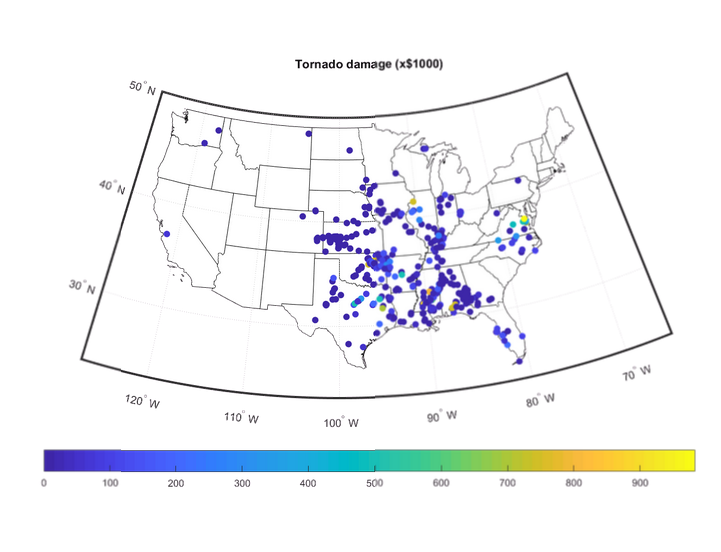

The storm event data are available as .csv files which are freely available from the [National Oceaning and Atomospheric Administration](http://www.noaa.gov/) (NOAA):  [ftp://ftp.ncdc.noaa.gov/pub/data/swdi/stormevents/csvfiles/](ftp://ftp.ncdc.noaa.gov/pub/data/swdi/stormevents/csvfiles/) 

# Access Storm Event Data 

The historical storm data are organized as text files by year in one directory and are a little over than **1 GB total**.

All of the files have the same file and data formatting.

clear;
d = dir('StormData');
totFileSize = sum([d.bytes])

totFileSize = 1.0605e+09

## Access data using `datastore`

A [`datastore`](http://www.mathworks.com/help/matlab/import_export/what-is-a-datastore.html) is ideal for managing the data and file read information when working with a single large file or a number of files with the same data formatting. The data is accessed through the datastore, and you can provide information about how best to represent and eventually read or operate on the data. The `datastore` enables you to easily read the data in "chunks" or create a `tall array` to work with the out-of-memory data as if it were one array.

Create a `datastore` to represent all storm event data in the directory. Ensure the `string` data type is used for all text data in the files. Since we know we want this without looking at the data, we can pass it to the function right away. Otherwise, we will use the `datastore` to examine the data and adjust any additional properties.

fileLoc = fullfile('StormData','StormEvents_details-ftp_v1.0_*.csv')

fileLoc = 'StormData\StormEvents_details-ftp_v1.0_*.csv'

ds = datastore(fileLoc,'TextType','string'); 

Examine methods for datastore

methods(ds)


Methods for class matlab.io.datastore.TabularTextDatastore:

TabularTextDatastore  
copy                  
delete                
hasdata               
numpartitions         
partition             
preview               
read                  
readall               
reset                 


Methods of matlab.io.datastore.TabularTextDatastore inherited from handle.



## Examine file properties

The variable `ds` contains information about the data within all files specified in the directory. You can access the properties related to the datastore, including information about the files and underlying data, using **dot notation**: `VariableName`**.**`PropertyName`  

fnames = ds.Files

fnames = 37×1 cell array
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1980_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1981_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1982_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1983_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1984_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1985_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d1986_c20160223.csv'
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherE

The selected files can also be managed through the `datastore` properties. Start with the most recent file (2016) since this is our first look into the data. We will use all of the data in later calculations when finished exploring and prototyping with a subset of the data. 

ds.Files = fnames(end);
ds.Files

ans = cell
    'C:\Users\shirang\Documents\Seminars\Expo2017\WeatherEventAnalysis\StormData\StormEvents_details-ftp_v1.0_d2016_c20170123.csv'


## Modify data properties 

Adjust `datastore` properties to read the storm data appropriately. Information about each variable (column) in the file can be specified including the data types, variable names, and which variables to select. Explore the selected data with the `preview` function, which returns the first few rows. 

Specify the formats to best represent the data (format specifications for text files are listed [here](http://www.mathworks.com/help/matlab/ref/textscan.html#inputarg_formatSpec)). When specifying a single format for multiple variables, you can select the variables and pass a cell array with one format. Since we've never looked at this data before, we aren't sure what some of the variables contain in the file since the first few rows are missing. Reading that data as text initially can be helpful in examining this (and can avoid errors from unexpected characters as a step in troubleshooting).

ds.SelectedFormats([9,12,13]) = {'%C'};                       % Categorical (state,month,event_type)                      
ds.SelectedFormats([18,20]) = {'%{dd-MMM-yy HH:mm:ss}D'};     % Datetime   
ds.SelectedFormats(25:end) = {'%q'};                          % Text (string)
preview(ds)

ans = 8×51 table
    BEGIN_YEARMONTH    BEGIN_DAY    BEGIN_TIME    END_YEARMONTH    END_DAY    END_TIME    EPISODE_ID     EVENT_ID         STATE         STATE_FIPS    YEAR    MONTH_NAME       EVENT_TYPE        CZ_TYPE    CZ_FIPS       CZ_NAME        WFO      BEGIN_DATE_TIME      CZ_TIMEZONE      END_DATE_TIME       INJURIES_DIRECT    INJURIES_INDIRECT    DEATHS_DIRECT    DEATHS_INDIRECT    DAMAGE_PROPERTY    DAMAGE_CROPS          SOURCE           MAGNITUDE    MAGNITUDE_TYPE    FLOOD_CAUSE

Change the variable names to lower case and adjust the names containing `'date_time'` (this could be confusing since the dates are `datetime` variables in MATLAB).

ds.VariableNames = lower(ds.VariableNames);
ds.VariableNames = replace(ds.VariableNames,'date_time','timestamp');
vars = ds.VariableNames 

vars = 1×51 cell array
    'begin_yearmonth'    'begin_day'    'begin_time'    'end_yearmonth'    'end_day'    'end_time'    'episode_id'    'event_id'    'state'    'state_fips'    'year'    'month_name'    'event_type'    'cz_type'    'cz_fips'    'cz_name'    'wfo'    'begin_timestamp'    'cz_timezone'    'end_timestamp'    'injuries_direct'    'injuries_indirect'    'deaths_direct'    'deaths_indirect'    'damage_property'    'damage_crops'    'source'    'magnitude'    'magnitude_type'    'flood_cause'    'category'    'tor_f_scale'    'tor_length'    'tor_width'    'tor_other_wfo'    'tor_other_cz_state'    'tor_other_cz_fips'    'tor_other_cz_name'    'begin_range'    'begin_azimuth'    'begin_location'    'end_range'    'end_azimuth'    'end_location'    'begin_lat'    'begin_lon'    'end_lat'    'end_lon'    'episode_narrative'    'event_narrative'    'data_source'


**Filter the variables** down to a subset of interest for this study including **locations, event narratives, and variables representing damage costs, dates, and times**. Use functions to select variables with exact matches like `state` and `year` and also those containing certain keywords like `lat` and `lon(`latitude and longitude)

idx = ismember(vars,{'year','state'}) | ...         
    contains(vars,{'lat','lon','day', ...           
        'timestamp','damage','event'})    

idx = 1×51 logical array
   0   1   0   0   1   0   0   1   1   0   1   0   1   0   0   0   0   1   0   1   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   0   1   0


ds.SelectedVariableNames = vars(idx);
pre = preview(ds)

pre = 8×15 table
    begin_day    end_day     event_id         state         year       event_type         begin_timestamp        end_timestamp       damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                                                               event_narrative                                                                                         
    _________    _______    __________    ______________    ____    _________________    __________________    __________________    _______________    

## Read subset of the data 

Choose how much data to read from the datastore **or **work directly with the out-of-memory data using a `tall` array.

- `read`: Read a subset of data (based on `ReadSize`)

- `readall`: Read all data into memory

Read the **first subset** of data into memory for prototyping and then scale to the full data set using a `tall` array after initial exploration. The amount of data to read can be adjusted by setting the `ReadSize`. 

ds.ReadSize = 2000;
data = read(ds);  % Table output

# Preprocess and Reorganize Data Using `timetable`

Eexplore the first 8 rows of the table.

head(data)

ans = 8×15 table
    begin_day    end_day     event_id         state         year       event_type         begin_timestamp        end_timestamp       damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                                                               event_narrative                                                                                         
    _________    _______    __________    ______________    ____    _________________    __________________    __________________    _______________    

## Preprocess date and time data 

The table contains dates and times available in several forms. There are **beginning and ending time stamps** and the dates are also represented as separate numeric components for the year and day. 

Access the data in the table using the variable names or by variable type. ([Example: Access Data in a Table](http://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html))

data.begin_timestamp(1:5)

ans = 5×1 datetime array
   22-Jul-16 16:10:00
   15-Jul-16 17:15:00
   15-Jul-16 17:25:00
   16-Jul-16 12:46:00
   15-Jul-16 14:28:00


The dates and times are best represented in MATLAB as `datetime` variables for time stamps and `duration` or `calendarDuration` for relative or elaped times. ([Example: Represent Dates and Times in MATLAB](http://www.mathworks.com/help/matlab/matlab_prog/represent-date-and-times-in-MATLAB.html))

Adjust the format of the `datetime` display to view the** full year.**

data.begin_timestamp.Format = 'dd/MMM/yyyy HH:mm:ss';
data.begin_timestamp(1:5)

ans = 5×1 datetime array
   22/Jul/2016 16:10:00
   15/Jul/2016 17:15:00
   15/Jul/2016 17:25:00
   16/Jul/2016 12:46:00
   15/Jul/2016 14:28:00


Determine the duration of each storm from the begin and end time stamps. 

data.storm_duration = data.end_timestamp - data.begin_timestamp;
data.storm_duration(1:5)

ans = 5×1 duration array
   00:05:00
   00:00:00
   00:00:00
   00:00:00
   00:07:00


What was the longest storm?

[maxDur,idx] = max(data.storm_duration)

maxDur = duration
   743:59:00


idx = 260

longestStormDur = data(idx,:)

longestStormDur = 1×16 table
    begin_day    end_day     event_id      state      year    event_type      begin_timestamp         end_timestamp       damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                       event_narrative                                                      storm_duration
    _________    _______    __________    ________    ____    __________    ____________________    __________________    _______________    ____________    _________  

There was a flood event during the entire month of January in Arkansas. 

Get a feel for all storm **durations** with a histogram (Zoom, Pan, and use the Data Cursor in the figure within the Live Script to explore various regions of the plot and select Update Code to keep the desired axes limits)

Most storms are in the first bin.

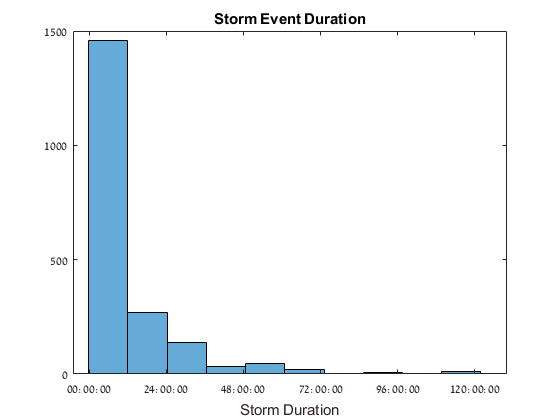

histogram(data.storm_duration)
xlabel('Storm Duration')
title('Storm Event Duration')
xlim([duration(-5,0,0),duration(130,0,0)])

## Create a `timetable`

Preprocess the data using a [`timetable`](http://www.mathworks.com/help/matlab/timetables.html) (2016b), which is ideal for preprocessing **time-stamped data**. This is similar to the table data type, but with `RowTimes` instead of `RowNames` and additional functionality specific to working with time-stamped data. 

data = table2timetable(data);
head(data)

Note that the **first** `datetime` variable in the table was taken as the `RowTimes` of the timetable by default (any `datetime` or `duration` variable can be specified). 

Examine **methods** for timetable

methods(data) % retime, synchronize, sortrows...

Examine the **properties** of the timetable, which contain metadata about the timetable and variables.

data.Properties

When converting from a `table`, the variable name of the `RowTimes` specified is used to label the time dimension. The `DimensionNames` can be used to access the times in the `timetable` directly. Adjust the name of the time dimension. 

data.Properties.DimensionNames(1) = {'Time'};
data.Properties.DimensionNames

Explore the times.

[tmin,tmax] = bounds(data.Time)

This data represents a portion of the year 2016. We need to keep this in mind when exploring so we don't draw any conclusions before applying our analysis to the full data set. 

## Rearrange `timetable` variables

The additional date and time variables are in various positions of the timetable. Reorder the variables so all **date and time components** are arranged in the **last few columns. **

vars = data.Properties.VariableNames
idx = contains(vars,{'day','time','year','month'});
neworder = [vars(~idx),vars(idx)];
data = data(:,neworder);
head(data)

## Sort the data 

Timetables can have any time order and are easily **sorted** **by time**. Additional inputs can be specified to sort the data by a different variable and control other sorting options. You can determine whether a variable is sorted using [`issortedrows`](https://www.mathworks.com/help/matlab/ref/issortedrows.html) or [`issorted`](https://www.mathworks.com/help/matlab/ref/issorted.html).

issortedrows(data)
data = sortrows(data);
issortedrows(data)

Is the data regularly sampled?

isregular(data)

## Missing data

There are missing data (`NaN`, `<undefined>`,`NaT`) in a number of variables which may need different strategies. 

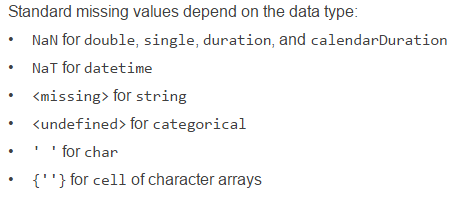

**Missing data functions** can help with each situation: standardize **what to consider missing, identify, remove, and fill **(with a variety of methods such as interpolation, filling with a constant, etc). 

- `standardizeMissing`

- `ismissing`

- `rmmissing (2016b)`

- `fillmissing (2016b)`

For example, remove rows containing *all* missing data. The default behavior of `rmmissing` is to remove rows with *any* missing values and this can be controlled through Name - Value Pairs. 

data = rmmissing(data,'MinNumMissing',width(data));

# Preprocess Text and Explore Storm Event Narratives 

Explore the first 8 rows of the table. 

head(data)

## Preprocess loacation variables

The `event_narrative` variable contains text data which can be processed and analyzed using the [`string`](http://www.mathworks.com/help/matlab/matlab_prog/represent-text-with-character-and-string-arrays.html) data type. However, the **damage and location variables would be better represented as numeric data** for analysis. The `string` data type can be useful for cleaning and preprocessing these variables and converting to the appropriate type. 

The latitude and longitude variables were imported as strings, but should be numeric (`double`) to perform calculations. Since there are multiple table variables (and could be many in other cases), we can use a loop to convert several variables in the table. Therefore, we should represent the current variable in the loop by either a numeric value or a variable with the name of interest. With dot indexing, you can put parenthesis around the number or variable name: `tableName.(1)` or `tableName.(varname)  `

locvars = {'begin_lat','begin_lon','end_lat','end_lon'};
for ii = 1:4
    vname = locvars{ii};                 
    data.(vname) = double(data.(vname));
end

head(data)

## Preprocess damage variables

Identify the remaining `string` variables in the `timetable` by type using `vartype` to identify variables by data type.

data(1:5,vartype('string'))

**Remove the K** in the damage variables using erase (2016b) and convert to the strings to numeric to determine the total damage for each storm.

data.damage_property = erase(data.damage_property,'K');
data.damage_property = double(data.damage_property);
data.damage_crops = erase(data.damage_crops,'K');
data.damage_crops = double(data.damage_crops);
data.damage_total = data.damage_crops + data.damage_property;
data(1:10,{'damage_property','damage_crops','damage_total'})

Add the units for these variables to the `timetable` (you can access properties by variable name in tables and timetables to assign the value).

data.Properties.VariableUnits({'damage_property',...
    'damage_crops','damage_total'}) = {'K$'};
data.Properties

## Explore event narratives text

The `event_narrative` variable is best represented in the current form as a `string`. The `string` functions are useful in exploration and analysis in addition to preprocessing as shown previously. 

data.event_narrative(1:20)

In the first 20 rows, there are several narratives describing **trees falling**. We can explore this further by identifying and counting various words in the string array. Identify and **count the number of events** which contain the words tree, road (or highway), and both. 

treeidx = contains(data.event_narrative,'tree','IgnoreCase',true); 
roadidx = contains(data.event_narrative,{'road','hwy','highway'},'IgnoreCase',true);
numtrees = nnz(treeidx)
numroads = nnz(roadidx)
numboth = nnz(treeidx & roadidx)

## Examine associated damage costs

Determine the **damage costs associated** with the words tree and road and compare the costs with a histogram. Plot the histograms separately to compare.

damage_tree = data.damage_property(treeidx);
damage_road = data.damage_property(roadidx);

histogram(damage_tree,20,'BinLimits',[1 100])
hold on
histogram(damage_road,20,'BinLimits',[1 100]) 
hold off
title('Damage Cost by Words in Narrative')
xlabel('Damage Cost ($1000)')
ylabel('Frequency')
legend('tree','road')

# Summary 

- datastore

- categircal, datetime, duration, string, timetable

- ismissing, rmmissing, fillmissing etc.